# Advent of Code

## `--- Day 3: Crossed Wires ---`

`Part 1`

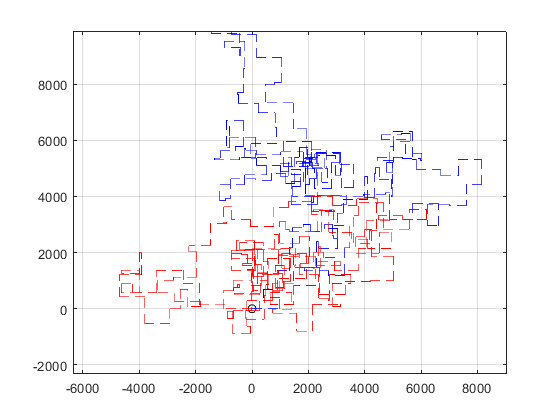

clear; close; clc
w1='R990,U408,L583,U275,R483,U684,R437,U828,R108,U709,R378,U97,R252,D248,R413,U750,R428,D545,R570,D795,L204,D975,L557,U160,L861,U106,R436,U934,R81,D237,R660,U704,L451,U135,R282,D391,R39,D109,R125,U918,R214,U481,R853,U825,L91,D763,R335,U868,R42,U218,R152,D429,R414,D607,R28,U436,R7,U770,L215,D373,R209,U440,L536,U120,R900,D46,R635,D75,R58,U267,L581,U474,L858,U172,R725,U54,R291,D274,L583,D743,L130,U563,R137,U524,R659,D997,R131,D364,R883,D222,R628,U579,R801,D890,L519,D749,L620,U60,L759,D759,R376,U769,L910,D570,L814,U954,L153,D42,L784,D66,L844,U29,L794,D342,L924,U825,R447,U828,R404,D52,L330,D876,R125,U203,R245,U936,R866,D804,L186,U693,L620,D722,L32,D735,L191,D217,R68,U209,L736,U365,R280,U608,L450,D240,L282,U434,R589,U94,R470,D5,R49,U407,R552,D651,L69,U518,L358,D130,L710,D929,L315,U345,L511,D229,L557,U44,L890,D702,L181,D61,L208,U553,R878,U354,R787,U624,L961,D92,L891,U70,R203,U255,R532,U154,R299,U934,L609,D985,R115,U757,L13,D368,R936,D742,L412,U346,R56,D67,R371,D175,R868,U107,R806,D530,L40,U153,R374,D223,R517,D481,L194,U545,L356,U906,L999,D885,R967,U407,L141,U927,L489,U959,L992,U638,R332,U51,R256,U901,L891,U803,L885,U804,L242,U180,R277,U693,R935,D253,L68,D153,L614,D596,L999,D633,R995,D803,R17,U303,L569,U231,R737,D970,L45,D860,L225,D65,R41,D313,R698,D340,R599,D531,R55,D568,L911,D547,R196,D228,R868,D227,R262,U525,R104,D625,R570,U968,L276,D586,R690,D73,L336,U287,R294,U148,R781,D395,R478,D804,L429,U872,L351,D910,L597,U726,L320,D964,R928,U2,R540,D325,L222';
w2='L998,U662,R342,U104,R140,U92,R67,D102,L225,U265,R641,U592,L295,D77,R415,U908,L640,D381,R312,U44,R424,D847,R892,D625,L337,D344,L917,D914,R127,D273,L627,U812,L200,D262,R226,U273,R911,U597,L888,U28,R921,U464,R254,U771,R818,D808,L239,D225,L280,U785,R322,D831,L622,U506,R139,U12,L491,D572,L172,U685,R54,U747,L812,D717,R874,U428,L867,U174,R360,D36,R217,D539,R210,D791,L82,D665,L190,D313,R649,U849,R63,U385,R105,U806,L207,U697,L823,D272,R830,D952,L386,U987,R775,U517,R139,D756,R545,D973,L743,D286,R261,U448,R946,U884,L903,D142,R28,D374,R259,U403,R689,D245,L302,D134,R710,U762,L67,D561,R801,D140,L887,U346,L227,U682,L350,D218,L711,U755,R226,D277,R114,D61,R992,U602,L191,U640,R733,D329,R862,U242,R754,D161,L52,D974,L251,D444,L552,U977,R174,U483,R869,D955,R925,U693,R610,D353,L843,U148,L866,D167,R412,D31,L847,D979,L282,D797,L837,U473,L402,U193,L332,D603,R48,D589,L760,D673,L843,U428,R779,D592,L688,D141,R851,D642,R559,U939,R999,D64,L297,U817,R670,U322,L768,D936,L39,U95,L342,U849,L692,U714,L732,D734,L373,U66,L577,D453,R336,U760,L217,U542,R920,U24,R529,D594,L34,D79,R877,D965,R932,U460,R879,U26,R803,U876,L780,U956,L235,D270,L315,D577,R835,U750,R414,D584,L828,U335,L563,U238,L815,U780,L550,U18,R743,D54,L816,U344,L806,D197,L518,D682,L835,U255,L666,U442,L286,D543,R102,D52,L570,D787,L763,D223,R279,D892,L828,D111,L554,D452,R575,D299,R932,D187,L439,U616,L278,D701,L360,D524,L891,U953,L896,U788,R776,U782,L71,D741,L652,U121,R669,D809,L662,U319,R392,D313,R870,U794,R937,D469,R571,D761,R947';
del1=isletter(w1); del2=isletter(w2);
w1d=w1; w2d=w2; w1n=w1; w2n=w2;
w1d(not(del1))=[]; w2d(not(del2))=[];
w1n(regexp(w1n,'[RULD]'))=[]; w2n(regexp(w2n,'[RULD]'))=[];
w1n=str2num(w1n); w2n=str2num(w2n);
x=[0 0]; y=[0 0];
plot(x,y,'ko'); hold on; grid on
axis([-4000 10000 -100 11000])
C1={}; con=1; %C1{1,1}=x; C1{2,1}=y;
for i=1:1:length(w1d)
    %pause(.1)
    if w1d(i)=='R'
        x=[x(2) x(2)+w1n(i)];
        y=[y(2) y(2)];
        plot(x,y,'b--')
    elseif w1d(i)=='L'
        x=[x(2) x(2)-w1n(i)];
        y=[y(2) y(2)];
        plot(x,y,'b--')
         
    elseif w1d(i)=='U'
        x=[x(2) x(2)];
        y=[y(2) y(2)+w1n(i)]; 
        plot(x,y,'b--')
    elseif w1d(i)=='D'
        x=[x(2) x(2)];
        y=[y(2) y(2)-w1n(i)];
        plot(x,y,'b--')
    end  
    C1{1,con}=x; C1{2,con}=y;
    con=con+1;
end
x=[0 0]; y=[0 0];
C2={}; con2=1; %C2{1,1}=x; C2{2,1}=y;
for j=1:1:length(w2d)
    if w2d(j)=='R'
        x=[x(2) x(2)+w2n(j)];
        y=[y(2) y(2)];
        plot(x,y,'r--')
    elseif w2d(j)=='L'
        x=[x(2) x(2)-w2n(j)];
        y=[y(2) y(2)];
        plot(x,y,'r--')
    elseif w2d(j)=='U'
        x=[x(2) x(2)];
        y=[y(2) y(2)+w2n(j)]; 
        plot(x,y,'r--')
    elseif w2d(j)=='D'
        x=[x(2) x(2)];
        y=[y(2) y(2)-w2n(j)];
        plot(x,y,'r--')
xlim([-6352 9048])
ylim([-2323 9887])
    end
    C2{1,con2}=x; C2{2,con2}=y;
    con2=con2+1;
end 

Part 2

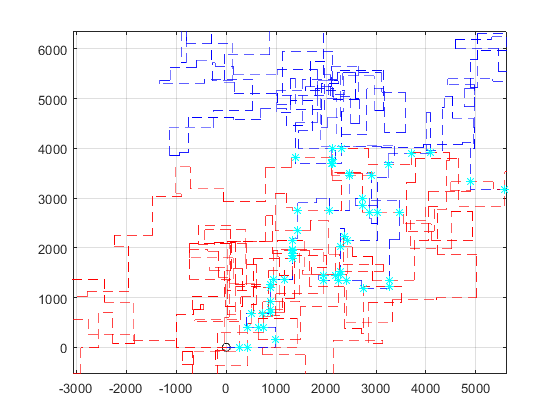

cint={}; con3=1; cint1=[];
for i1=1:1:length(C1)
    x=sort(C1{1,i1}); y=sort(C1{2,i1});
    for i2=1:1:length(C2)
        x1=sort(C2{1,i2}); y1=sort(C2{2,i2});
        if length(unique(x))==1
            if length(unique(y1))==1
                temp1=x1(1):1:x1(2);
                temp2=y(1):1:y(2);
                if ismember(x(1),temp1) && ismember(y1(1),temp2)
                    cint{1,con3}=[x(1) y1(1)];
                    cint{2,con3}=[i1 i2];
                    cint1(1,con3)=sum(abs([x(1) y1(1)]));
                    con3=con3+1;
                    plot(x(1),y1(1),'c*')
                end
            end
        elseif length(unique(y))==1
            if length(unique(x1))==1
                temp1=x(1):1:x(2);
                temp2=y1(1):1:y1(2);
                if ismember(x1(1),temp1) && ismember(y(1),temp2)
                    cint{1,con3}=[x1(1) y(1)];
                    cint{2,con3}=[i1 i2];
                    cint1(1,con3)=sum(abs([x1(1) y(1)]));
                    con3=con3+1;
                    plot(x1(1),y(1),'c*')
                    
xlim([-3070 5623])
ylim([-535 6357])
                end    
            end
        end
    end
end

disp(min(cint1))

   258



sumsteps=[];
for fi=1:1:length(cint1)
    fs=cint{2,fi};    
    fs1=cint{1,fi}; 
    p1=C1{1,fs(1)};
    if length(unique(p1))==1
        p1=C1{2,fs(1)};
    end
    p2=C2{2,fs(2)};
    if length(unique(p2))==1
        p2=C2{1,fs(2)};
    end
    q=sum(w1n(1:1:(fs(1)-1)))+sum(w2n(1:1:(fs(2)-1)));
    p=abs(p1(1)-fs1(1))+abs(p2(1)-fs1(2));
    sumsteps(1,fi)=p+q;
end
disp(min(sumsteps))

       12304

